`%% COMPARE_CONDITIONS.m
% Compares cardiac features across conditions in 5 sections:
%   Section 1 — Normal vs Normal       (intra-condition consistency)
%   Section 2 — Bradycardia vs Brady   (intra-condition consistency)
%   Section 3 — Tachycardia vs Tachy   (intra-condition consistency)
%   Section 4 — AFib vs AFib           (intra-condition consistency)
%   Section 5 — All 4 conditions       (inter-condition comparison)
%
% REQUIRES: extract_features.m + data/ folder with 8 CSVs

clear; clc; close all;

%% CONFIGURATION
fs = 360;

dataset_paths = {
    'Normal',      'data/normal_1.csv',  'data/normal_2.csv';
    'Bradycardia', 'data/brady_1.csv',   'data/brady_2.csv';
    'Tachycardia', 'data/tachy_1.csv',   'data/tachy_2.csv';
    'AFib',        'data/afib_1.csv',    'data/afib_2.csv';
};

conditions = {'Normal','Bradycardia','Tachycardia','AFib'};
n_cond     = numel(conditions);

% One colour per condition
colors = {[0.20 0.60 0.90],   % Normal      blue
          [0.15 0.70 0.40],   % Bradycardia green
          [0.95 0.35 0.25],   % Tachycardia red
          [0.95 0.60 0.10]};  % AFib        orange

feat_fields = {'mean_BPM','mean_IBI','SDNN','RMSSD','pNN50', ...
               'SD1','SD2','SD_ratio','CV','irregular_beats'};
feat_labels = {'Mean BPM','Mean IBI (ms)','SDNN (ms)','RMSSD (ms)', ...
               'pNN50 (%)','SD1 (ms)','SD2 (ms)','SD1/SD2','CV (%)','Irreg. Beats'};

%% LOAD ALL 8 DATASETS
fprintf('Loading all datasets...\n\n');

Loading all datasets...




======== FEATURE EXTRACTION SUMMARY ========
  Mode            : PPG
  Valid IBIs      : 302
  Signal Quality  : 100.0%
---------------------------------------------
  Mean BPM        : 60.65
  Mean IBI        : 989.33 ms
  SDNN            : 31.11 ms
  RMSSD           : 18.86 ms
  pNN50           : 0.66%
---------------------------------------------
  SD1             : 13.36 ms
  SD2             : 41.98 ms
  SD1/SD2 ratio   : 0.3182
---------------------------------------------
  CV              : 3.14%
  Irregular beats : 0



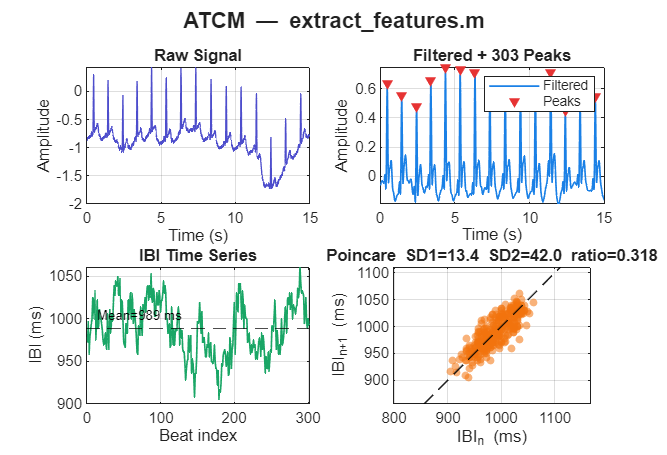

  Normal dataset 1 -> BPM=60.6  SD_ratio=0.318



======== FEATURE EXTRACTION SUMMARY ========
  Mode            : PPG
  Valid IBIs      : 421
  Signal Quality  : 100.0%
---------------------------------------------
  Mean BPM        : 84.29
  Mean IBI        : 711.81 ms
  SDNN            : 37.95 ms
  RMSSD           : 19.57 ms
  pNN50           : 1.90%
---------------------------------------------
  SD1             : 13.85 ms
  SD2             : 51.77 ms
  SD1/SD2 ratio   : 0.2676
---------------------------------------------
  CV              : 5.33%
  Irregular beats : 0



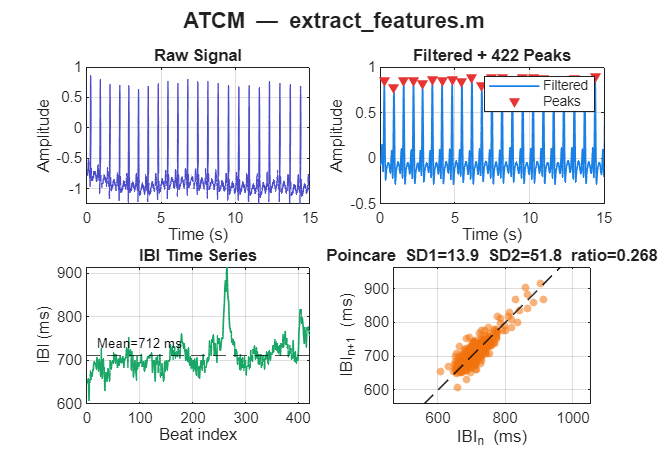

  Normal dataset 2 -> BPM=84.3  SD_ratio=0.268



======== FEATURE EXTRACTION SUMMARY ========
  Mode            : PPG
  Valid IBIs      : 219
  Signal Quality  : 100.0%
---------------------------------------------
  Mean BPM        : 44.01
  Mean IBI        : 1363.38 ms
  SDNN            : 14.38 ms
  RMSSD           : 8.41 ms
  pNN50           : 0.00%
---------------------------------------------
  SD1             : 5.96 ms
  SD2             : 19.45 ms
  SD1/SD2 ratio   : 0.3063
---------------------------------------------
  CV              : 1.05%
  Irregular beats : 0



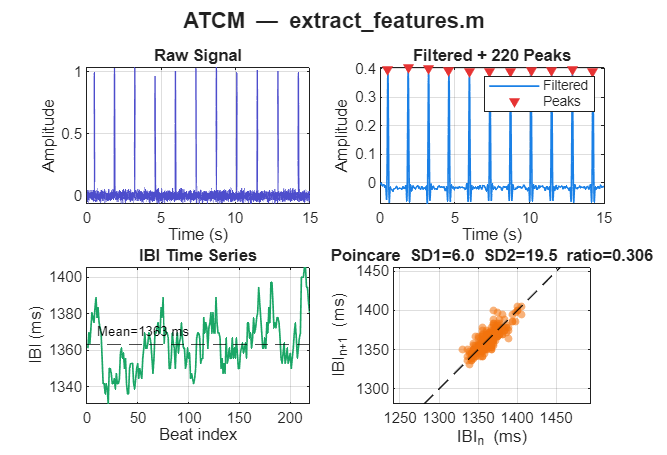

  Bradycardia dataset 1 -> BPM=44.0  SD_ratio=0.306



======== FEATURE EXTRACTION SUMMARY ========
  Mode            : PPG
  Valid IBIs      : 239
  Signal Quality  : 100.0%
---------------------------------------------
  Mean BPM        : 47.94
  Mean IBI        : 1251.64 ms
  SDNN            : 16.14 ms
  RMSSD           : 8.41 ms
  pNN50           : 0.00%
---------------------------------------------
  SD1             : 5.96 ms
  SD2             : 22.09 ms
  SD1/SD2 ratio   : 0.2699
---------------------------------------------
  CV              : 1.29%
  Irregular beats : 0



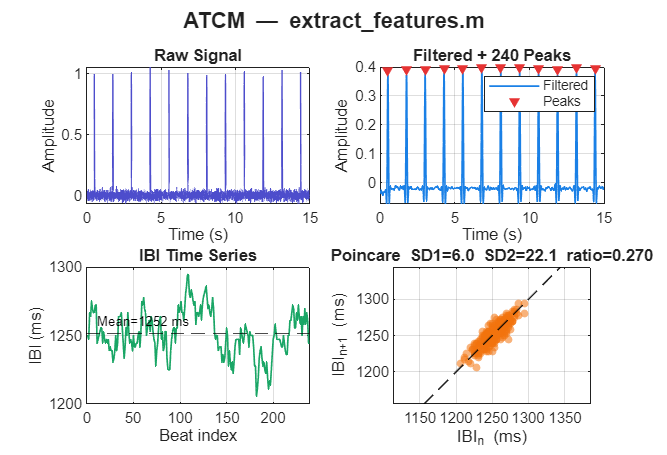

  Bradycardia dataset 2 -> BPM=47.9  SD_ratio=0.270



======== FEATURE EXTRACTION SUMMARY ========
  Mode            : PPG
  Valid IBIs      : 551
  Signal Quality  : 100.0%
---------------------------------------------
  Mean BPM        : 110.52
  Mean IBI        : 542.87 ms
  SDNN            : 8.55 ms
  RMSSD           : 5.87 ms
  pNN50           : 0.00%
---------------------------------------------
  SD1             : 4.15 ms
  SD2             : 11.36 ms
  SD1/SD2 ratio   : 0.3654
---------------------------------------------
  CV              : 1.57%
  Irregular beats : 0



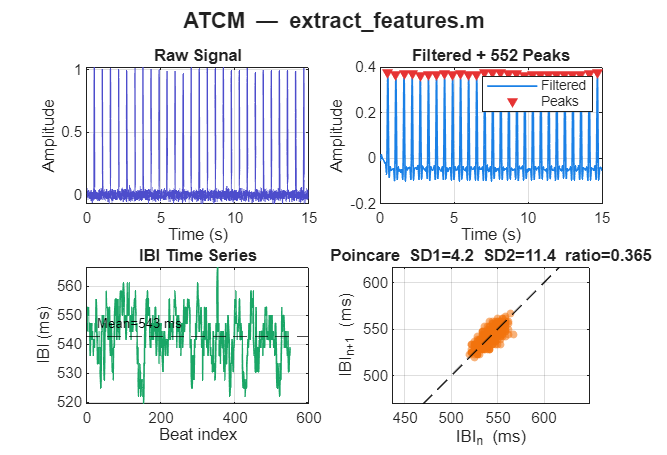

  Tachycardia dataset 1 -> BPM=110.5  SD_ratio=0.365



======== FEATURE EXTRACTION SUMMARY ========
  Mode            : PPG
  Valid IBIs      : 625
  Signal Quality  : 100.0%
---------------------------------------------
  Mean BPM        : 125.34
  Mean IBI        : 478.70 ms
  SDNN            : 8.70 ms
  RMSSD           : 5.43 ms
  pNN50           : 0.00%
---------------------------------------------
  SD1             : 3.84 ms
  SD2             : 11.68 ms
  SD1/SD2 ratio   : 0.3289
---------------------------------------------
  CV              : 1.82%
  Irregular beats : 0



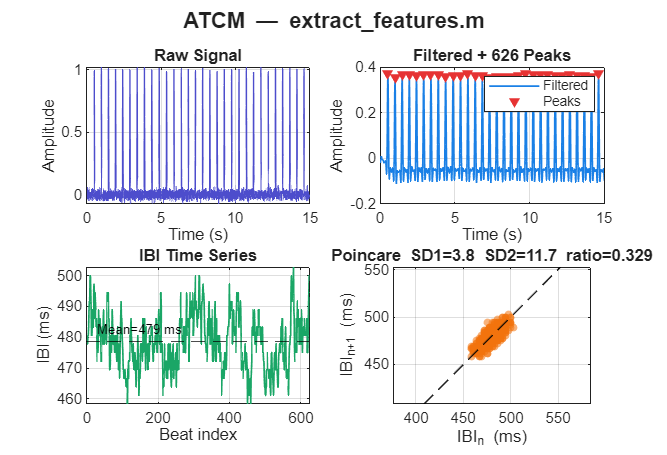

  Tachycardia dataset 2 -> BPM=125.3  SD_ratio=0.329



======== FEATURE EXTRACTION SUMMARY ========
  Mode            : PPG
  Valid IBIs      : 175
  Signal Quality  : 82.2%
---------------------------------------------
  Mean BPM        : 58.25
  Mean IBI        : 1030.02 ms
  SDNN            : 402.83 ms
  RMSSD           : 571.48 ms
  pNN50           : 94.83%
---------------------------------------------
  SD1             : 405.27 ms
  SD2             : 402.51 ms
  SD1/SD2 ratio   : 1.0068
---------------------------------------------
  CV              : 39.11%
  Irregular beats : 138



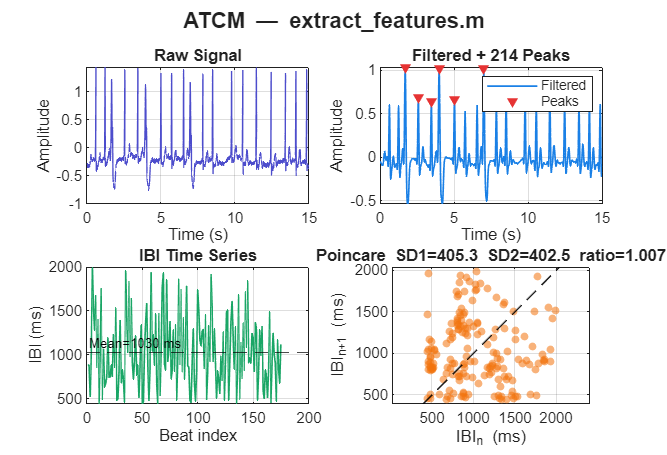

  AFib dataset 1 -> BPM=58.3  SD_ratio=1.007



======== FEATURE EXTRACTION SUMMARY ========
  Mode            : PPG
  Valid IBIs      : 431
  Signal Quality  : 100.0%
---------------------------------------------
  Mean BPM        : 86.26
  Mean IBI        : 695.55 ms
  SDNN            : 132.91 ms
  RMSSD           : 185.84 ms
  pNN50           : 65.35%
---------------------------------------------
  SD1             : 131.56 ms
  SD2             : 134.32 ms
  SD1/SD2 ratio   : 0.9795
---------------------------------------------
  CV              : 19.11%
  Irregular beats : 123



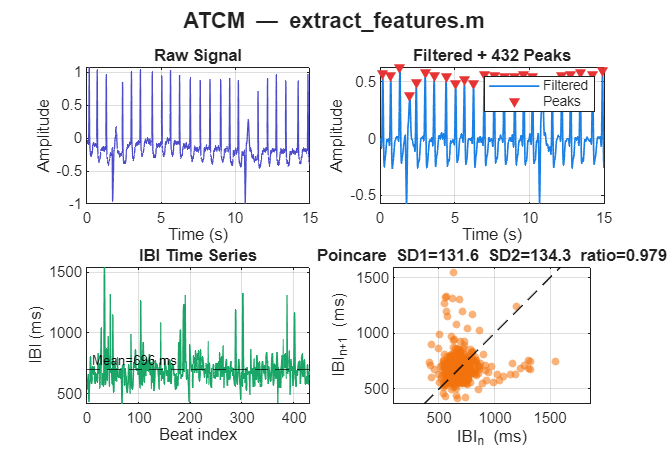

  AFib dataset 2 -> BPM=86.3  SD_ratio=0.979


cond_feats = cell(n_cond, 2);

for c = 1:n_cond
    for d = 1:2
        fpath = dataset_paths{c, d+1};
        if ~isfile(fpath)
            error('File not found: %s', fpath);
        end
        raw              = readmatrix(fpath, 'NumHeaderLines', 1);
        cond_feats{c, d} = extract_features(raw(:,1), fs);
        fprintf('  %s dataset %d -> BPM=%.1f  SD_ratio=%.3f\n', ...
                conditions{c}, d, cond_feats{c,d}.mean_BPM, cond_feats{c,d}.SD_ratio);
    end
end

fprintf('\nAll datasets loaded.\n\n');


All datasets loaded.





% =========================================================================
%% HELPER FUNCTION — intra-condition comparison plot
%   Used by Sections 1-4
% =========================================================================

function plot_intra(f1, f2, cname, clr, feat_fields, feat_labels)
% Plots Dataset 1 vs Dataset 2 for one condition

    figure('Name', sprintf('%s — Dataset 1 vs Dataset 2', cname), ...
           'NumberTitle','off','Position',[80 80 1100 800]);

    % ── Subplot 1: Feature bar comparison ────────────────────────────
    subplot(2,3,1);
    key_idx = [1,3,4,8,9,10];  % BPM, SDNN, RMSSD, SD_ratio, CV, Irreg
    key_lbl = feat_labels(key_idx);
    v1 = zeros(1,numel(key_idx));
    v2 = zeros(1,numel(key_idx));
    for k = 1:numel(key_idx)
        v1(k) = f1.(feat_fields{key_idx(k)});
        v2(k) = f2.(feat_fields{key_idx(k)});
    end
    b = bar([v1;v2]');
    b(1).FaceColor = clr;  b(1).FaceAlpha = 0.9;
    b(2).FaceColor = clr;  b(2).FaceAlpha = 0.45;
    set(gca,'XTickLabel',key_lbl,'XTick',1:numel(key_idx));
    xtickangle(20); ylabel('Value');
    legend('Dataset 1','Dataset 2','Location','northeast');
    title('Key Feature Comparison','FontWeight','bold');
    grid on; box on;

    % ── Subplot 2: IBI time series overlay ───────────────────────────
    subplot(2,3,2);
    plot(1:numel(f1.IBI), f1.IBI*1000, 'Color',clr,   'LineWidth',1.0); hold on;
    plot(1:numel(f2.IBI), f2.IBI*1000, 'Color',clr*0.5,'LineWidth',1.0,'LineStyle','--');
    xlabel('Beat index'); ylabel('IBI (ms)');
    title('IBI Time Series — DS1 vs DS2','FontWeight','bold');
    legend('Dataset 1','Dataset 2','Location','best');
    grid on; box on; hold off;

    % ── Subplot 3: IBI histograms overlapping ────────────────────────
    subplot(2,3,3);
    histogram(f1.IBI*1000, 20,'FaceColor',clr,    'FaceAlpha',0.6,'EdgeColor','none'); hold on;
    histogram(f2.IBI*1000, 20,'FaceColor',clr*0.5,'FaceAlpha',0.6,'EdgeColor','none');
    xlabel('IBI (ms)'); ylabel('Count');
    title('IBI Distribution — DS1 vs DS2','FontWeight','bold');
    legend('Dataset 1','Dataset 2','Location','northeast');
    grid on; box on; hold off;

    % ── Subplot 4: Poincare DS1 ───────────────────────────────────────
    subplot(2,3,4);
    x1=f1.IBI(1:end-1)*1000; y1=f1.IBI(2:end)*1000;
    scatter(x1,y1,20,clr,'filled','MarkerFaceAlpha',0.55); hold on;
    lo=min(x1)-20; hi=max(x1)+20;
    plot([lo hi],[lo hi],'--k','LineWidth',0.8);
    xlabel('IBI_n (ms)'); ylabel('IBI_{n+1} (ms)');
    title(sprintf('Poincare DS1 — ratio=%.3f',f1.SD_ratio),'FontWeight','bold');
    axis equal; grid on; box on; hold off;

    % ── Subplot 5: Poincare DS2 ───────────────────────────────────────
    subplot(2,3,5);
    x2=f2.IBI(1:end-1)*1000; y2=f2.IBI(2:end)*1000;
    scatter(x2,y2,20,clr*0.5,'filled','MarkerFaceAlpha',0.55); hold on;
    lo=min(x2)-20; hi=max(x2)+20;
    plot([lo hi],[lo hi],'--k','LineWidth',0.8);
    xlabel('IBI_n (ms)'); ylabel('IBI_{n+1} (ms)');
    title(sprintf('Poincare DS2 — ratio=%.3f',f2.SD_ratio),'FontWeight','bold');
    axis equal; grid on; box on; hold off;

    % ── Subplot 6: Feature table as text ─────────────────────────────
    subplot(2,3,6); axis off;
    col1 = {'Feature','Mean BPM','SDNN (ms)','RMSSD (ms)','SD1/SD2','CV (%)','Irreg. Beats'};
    col2 = {'DS1', sprintf('%.1f',f1.mean_BPM), sprintf('%.2f',f1.SDNN), ...
            sprintf('%.2f',f1.RMSSD), sprintf('%.4f',f1.SD_ratio), ...
            sprintf('%.2f',f1.CV), sprintf('%d',f1.irregular_beats)};
    col3 = {'DS2', sprintf('%.1f',f2.mean_BPM), sprintf('%.2f',f2.SDNN), ...
            sprintf('%.2f',f2.RMSSD), sprintf('%.4f',f2.SD_ratio), ...
            sprintf('%.2f',f2.CV), sprintf('%d',f2.irregular_beats)};
    tbl  = [col1', col2', col3'];
    uitable('Parent',gcf,'Data',tbl, ...
            'ColumnName',{'Feature','Dataset 1','Dataset 2'}, ...
            'Units','normalized','Position',[0.67 0.05 0.30 0.40], ...
            'FontSize',8,'RowName',[]);

    sgtitle(sprintf('%s — Dataset 1 vs Dataset 2',cname), ...
            'FontSize',13,'FontWeight','bold','Color',clr);

    % Console summary
    fprintf('\n=== %s: Dataset 1 vs Dataset 2 ===\n',upper(cname));
    fprintf('%-18s %-12s %-12s\n','Feature','Dataset 1','Dataset 2');
    fprintf('%s\n',repmat('-',1,44));
    for k = 1:numel(feat_fields)
        fprintf('%-18s %-12.3f %-12.3f\n', feat_labels{k}, ...
                f1.(feat_fields{k}), f2.(feat_fields{k}));
    end
    fprintf('%s\n',repmat('-',1,44));
end


% =========================================================================
%% SECTION 1 — NORMAL vs NORMAL
% =========================================================================
fprintf('\n>>> SECTION 1: Normal vs Normal\n');


>>> SECTION 1: Normal vs Normal


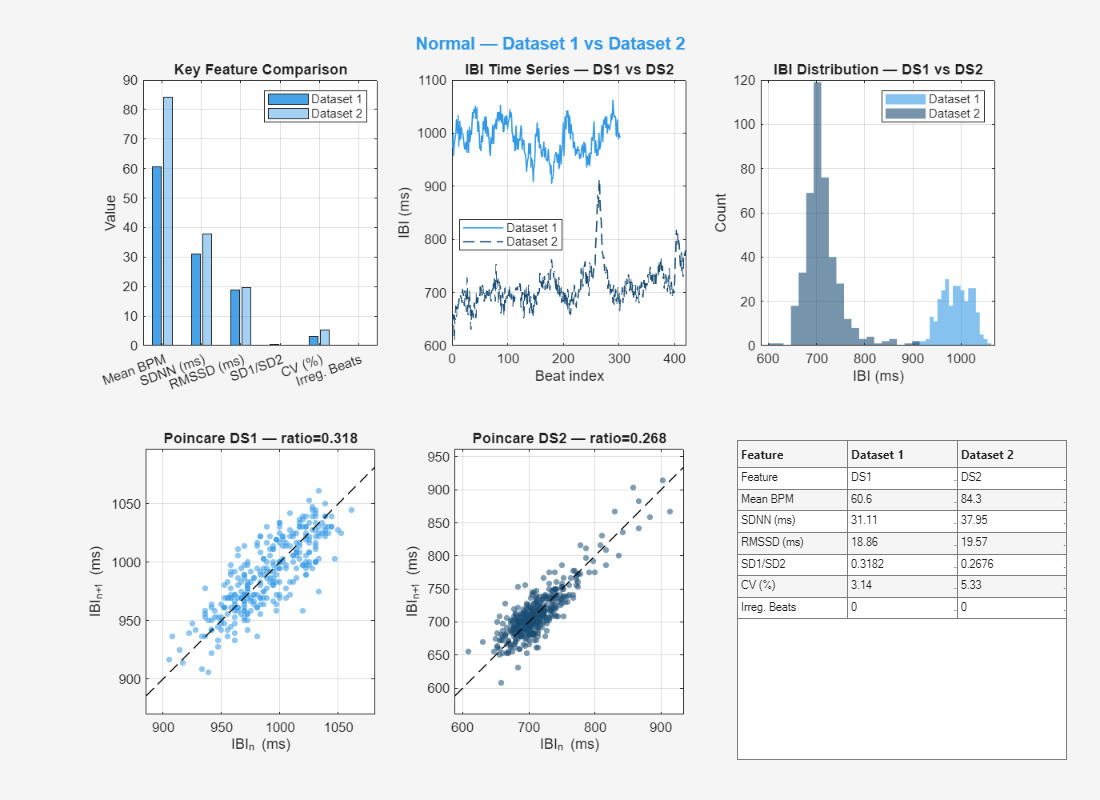


=== NORMAL: Dataset 1 vs Dataset 2 ===
Feature            Dataset 1    Dataset 2   
--------------------------------------------
Mean BPM           60.647       84.292      
Mean IBI (ms)      989.330      711.811     
SDNN (ms)          31.108       37.949      
RMSSD (ms)         18.860       19.571      
pNN50 (%)          0.664        1.905       
SD1 (ms)           13.358       13.854      
SD2 (ms)           41.982       51.775      
SD1/SD2            0.318        0.268       
CV (%)             3.144        5.331       
Irreg. Beats       0.000        0.000       
--------------------------------------------


plot_intra(cond_feats{1,1}, cond_feats{1,2}, 'Normal', colors{1}, feat_fields, feat_labels);



% =========================================================================
%% SECTION 2 — BRADYCARDIA vs BRADYCARDIA
% =========================================================================
fprintf('\n>>> SECTION 2: Bradycardia vs Bradycardia\n');


>>> SECTION 2: Bradycardia vs Bradycardia


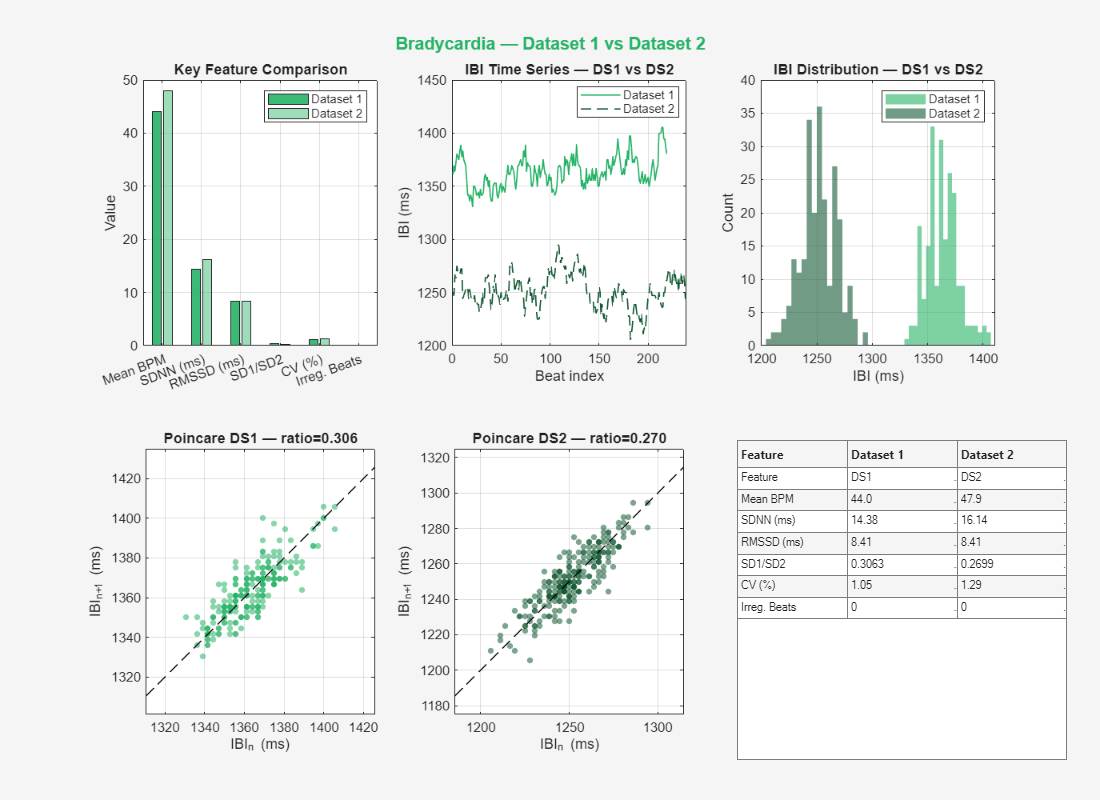


=== BRADYCARDIA: Dataset 1 vs Dataset 2 ===
Feature            Dataset 1    Dataset 2   
--------------------------------------------
Mean BPM           44.008       47.937      
Mean IBI (ms)      1363.382     1251.639    
SDNN (ms)          14.376       16.145      
RMSSD (ms)         8.407        8.411       
pNN50 (%)          0.000        0.000       
SD1 (ms)           5.958        5.960       
SD2 (ms)           19.451       22.085      
SD1/SD2            0.306        0.270       
CV (%)             1.054        1.290       
Irreg. Beats       0.000        0.000       
--------------------------------------------


plot_intra(cond_feats{2,1}, cond_feats{2,2}, 'Bradycardia', colors{2}, feat_fields, feat_labels);



% =========================================================================
%% SECTION 3 — TACHYCARDIA vs TACHYCARDIA
% =========================================================================
fprintf('\n>>> SECTION 3: Tachycardia vs Tachycardia\n');


>>> SECTION 3: Tachycardia vs Tachycardia


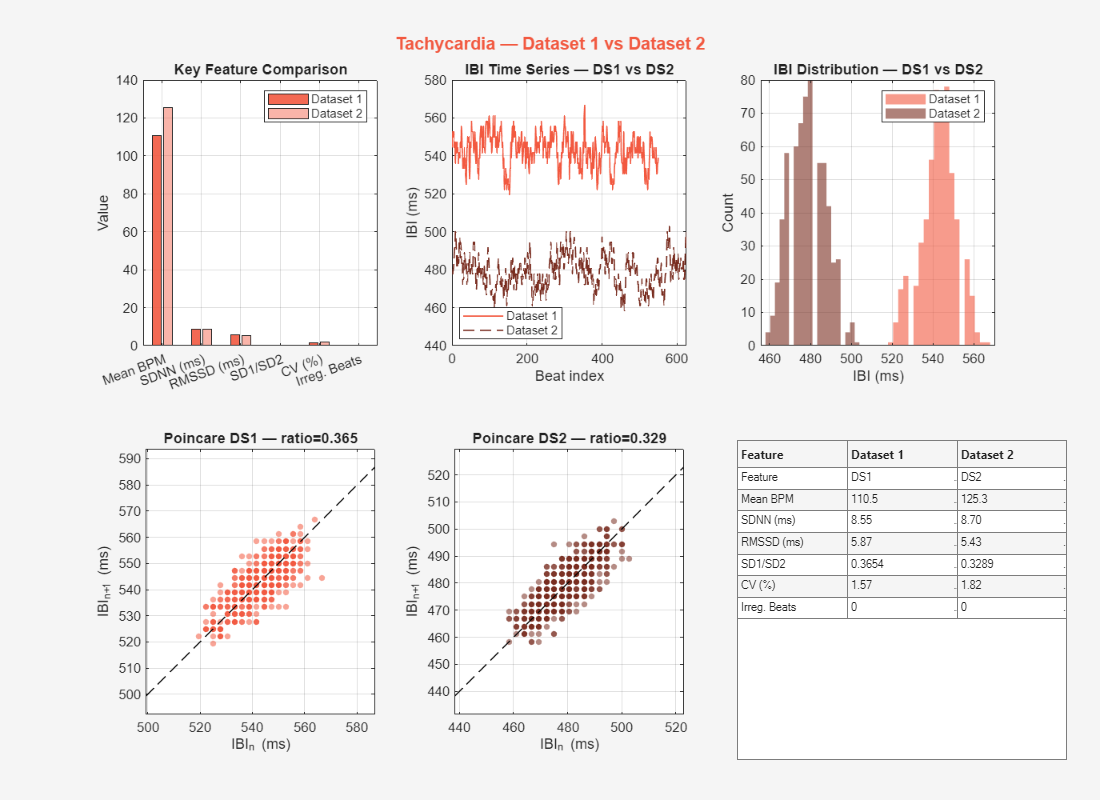


=== TACHYCARDIA: Dataset 1 vs Dataset 2 ===
Feature            Dataset 1    Dataset 2   
--------------------------------------------
Mean BPM           110.524      125.340     
Mean IBI (ms)      542.867      478.698     
SDNN (ms)          8.545        8.697       
RMSSD (ms)         5.865        5.427       
pNN50 (%)          0.000        0.000       
SD1 (ms)           4.151        3.841       
SD2 (ms)           11.360       11.677      
SD1/SD2            0.365        0.329       
CV (%)             1.574        1.817       
Irreg. Beats       0.000        0.000       
--------------------------------------------


plot_intra(cond_feats{3,1}, cond_feats{3,2}, 'Tachycardia', colors{3}, feat_fields, feat_labels);



% =========================================================================
%% SECTION 4 — AFIB vs AFIB
% =========================================================================
fprintf('\n>>> SECTION 4: AFib vs AFib\n');


>>> SECTION 4: AFib vs AFib


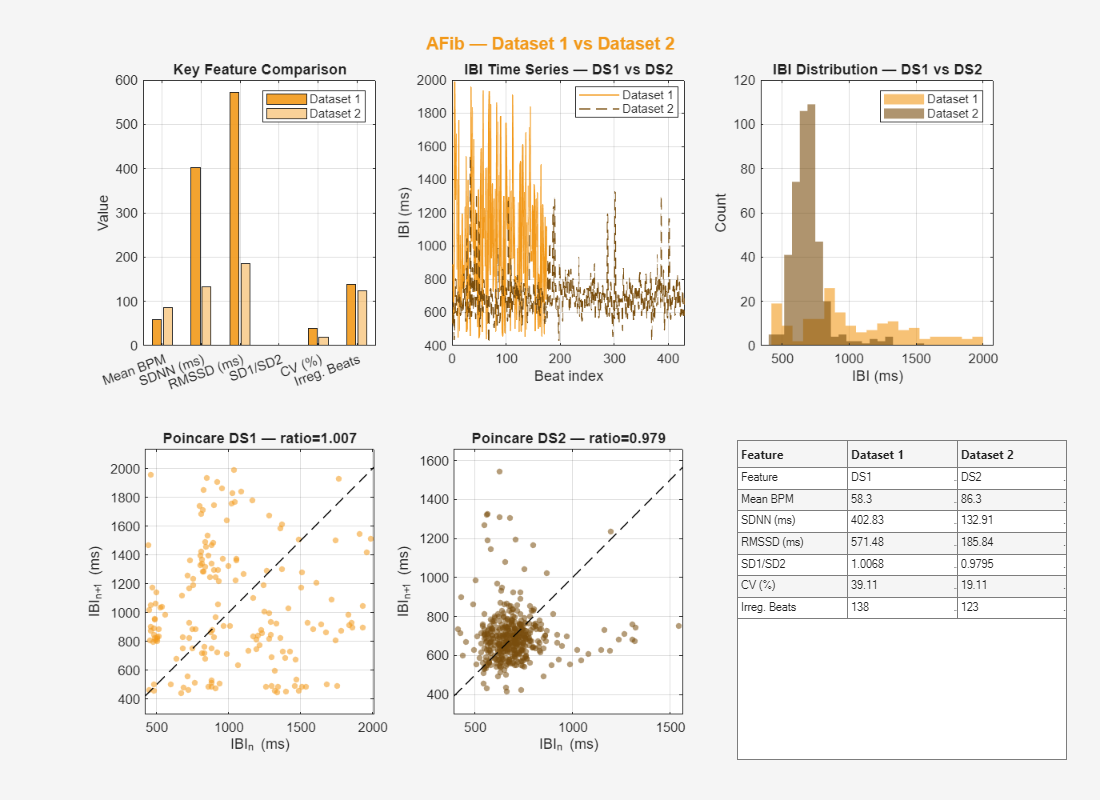


=== AFIB: Dataset 1 vs Dataset 2 ===
Feature            Dataset 1    Dataset 2   
--------------------------------------------
Mean BPM           58.252       86.262      
Mean IBI (ms)      1030.016     695.553     
SDNN (ms)          402.828      132.912     
RMSSD (ms)         571.484      185.845     
pNN50 (%)          94.828       65.349      
SD1 (ms)           405.266      131.565     
SD2 (ms)           402.510      134.321     
SD1/SD2            1.007        0.979       
CV (%)             39.109       19.109      
Irreg. Beats       138.000      123.000     
--------------------------------------------


plot_intra(cond_feats{4,1}, cond_feats{4,2}, 'AFib', colors{4}, feat_fields, feat_labels);



% =========================================================================
%% SECTION 5 — ALL 4 CONDITIONS TOGETHER
% =========================================================================
fprintf('\n>>> SECTION 5: All 4 Conditions Together\n\n');


>>> SECTION 5: All 4 Conditions Together




% Compute mean per condition
n_feat      = numel(feat_fields);
mean_matrix = zeros(n_cond, n_feat);
for c = 1:n_cond
    for f = 1:n_feat
        v = [];
        for d = 1:2
            if ~isempty(cond_feats{c,d})
                v(end+1) = cond_feats{c,d}.(feat_fields{f}); %#ok
            end
        end
        mean_matrix(c,f) = mean(v);
    end
end

% -- 5a: Feature comparison table --
fprintf('%-18s', 'Feature');

Feature           

for c = 1:n_cond; fprintf('%-16s', conditions{c}); end

Normal          Bradycardia     Tachycardia     AFib            

fprintf('\n%s\n',repmat('-',1,18+16*n_cond));


----------------------------------------------------------------------------------


for f = 1:n_feat
    fprintf('%-18s', feat_labels{f});
    for c = 1:n_cond; fprintf('%-16.3f', mean_matrix(c,f)); end
    fprintf('\n');
end

Mean BPM          

72.470          45.973          117.932         72.257          

Mean IBI (ms)     

850.570         1307.510        510.782         862.784         

SDNN (ms)         

34.529          15.260          8.621           267.870         

RMSSD (ms)        

19.215          8.409           5.646           378.665         

pNN50 (%)         

1.285           0.000           0.000           80.088          

SD1 (ms)          

13.606          5.959           3.996           268.415         

SD2 (ms)          

46.878          20.768          11.519          268.416         

SD1/SD2           

0.293           0.288           0.347           0.993           

CV (%)            

4.238           1.172           1.695           29.109          

Irreg. Beats      

0.000           0.000           0.000           130.500         

fprintf('%s\n',repmat('-',1,18+16*n_cond));

----------------------------------------------------------------------------------


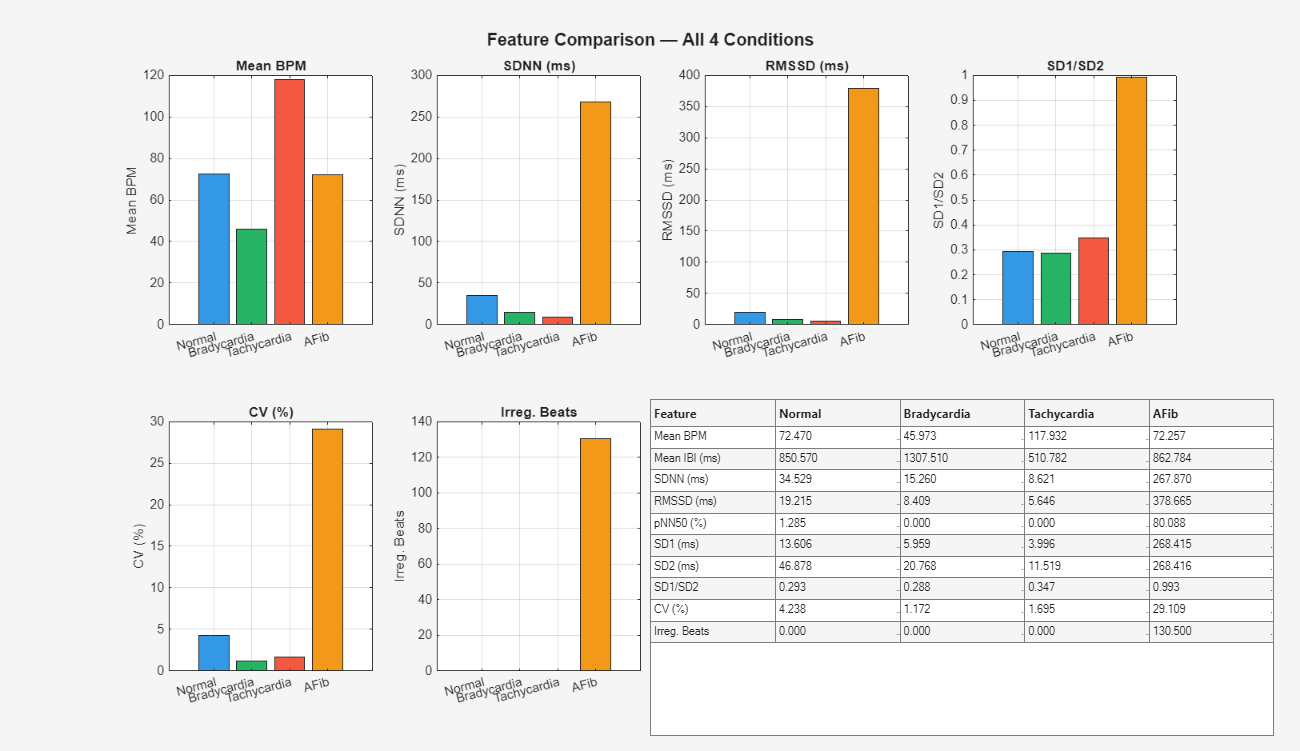


% -- 5b: Bar charts + feature table --
key_idx     = [1,3,4,8,9,10];
key_labels2 = feat_labels(key_idx);

figure('Name','All Conditions — Bar Charts','NumberTitle','off','Position',[60 60 1300 750]);
for k = 1:numel(key_idx)
    subplot(2,4,k);
    vals = mean_matrix(:,key_idx(k));
    b    = bar(vals,'FaceColor','flat');
    for c = 1:n_cond; b.CData(c,:) = colors{c}; end
    set(gca,'XTick',1:n_cond,'XTickLabel',conditions);
    xtickangle(15); ylabel(key_labels2{k});
    title(key_labels2{k},'FontWeight','bold');
    grid on; box on;
end

% Feature table — all 10 features x 4 conditions
subplot(2,4,[7 8]); axis off;
row_names = feat_labels';
tbl_data  = cell(numel(feat_fields), n_cond+1);
for f = 1:numel(feat_fields)
    tbl_data{f,1} = feat_labels{f};
    for c = 1:n_cond
        tbl_data{f,c+1} = sprintf('%.3f', mean_matrix(c,f));
    end
end
uitable('Parent',gcf,'Data',tbl_data, ...
        'ColumnName',[{'Feature'}, conditions], ...
        'Units','normalized','Position',[0.50 0.02 0.48 0.45], ...
        'FontSize',8,'RowName',[]);

sgtitle('Feature Comparison — All 4 Conditions','FontSize',13,'FontWeight','bold');

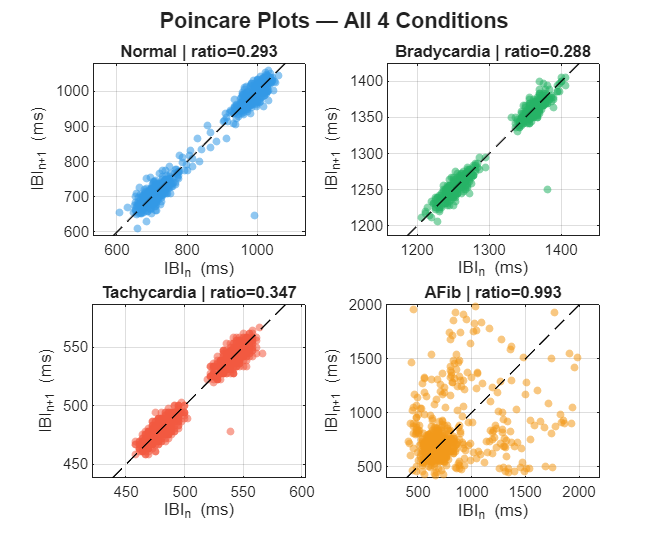


% -- 5c: Poincare 2x2 --
figure('Name','Poincare — All Conditions','NumberTitle','off','Position',[100 80 1000 800]);
for c = 1:n_cond
    subplot(2,2,c);
    all_ibi = [];
    for d = 1:2
        if ~isempty(cond_feats{c,d})
            all_ibi = [all_ibi; cond_feats{c,d}.IBI]; %#ok
        end
    end
    xi = all_ibi(1:end-1)*1000; yi = all_ibi(2:end)*1000;
    scatter(xi,yi,22,colors{c},'filled','MarkerFaceAlpha',0.55); hold on;
    lo=min(xi)-20; hi=max(xi)+20;
    plot([lo hi],[lo hi],'--k','LineWidth',0.8);
    xlabel('IBI_n (ms)'); ylabel('IBI_{n+1} (ms)');
    title(sprintf('%s | ratio=%.3f',conditions{c},mean_matrix(c,8)),'FontWeight','bold');
    axis equal; grid on; box on; hold off;
end
sgtitle('Poincare Plots — All 4 Conditions','FontSize',13,'FontWeight','bold');

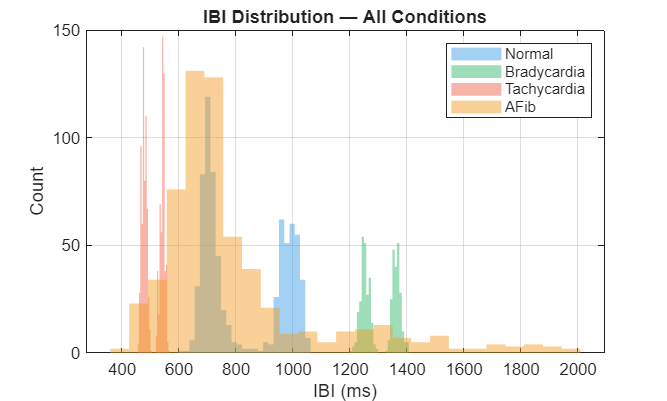


% -- 5d: IBI distributions --
figure('Name','IBI Distributions','NumberTitle','off','Position',[150 120 800 480]);
hold on; lgd = {};
for c = 1:n_cond
    all_ibi = [];
    for d = 1:2
        if ~isempty(cond_feats{c,d})
            all_ibi = [all_ibi; cond_feats{c,d}.IBI*1000]; %#ok
        end
    end
    histogram(all_ibi,25,'FaceColor',colors{c},'FaceAlpha',0.45,'EdgeColor','none');
    lgd{end+1} = conditions{c}; %#ok
end
xlabel('IBI (ms)'); ylabel('Count');
title('IBI Distribution — All Conditions');
legend(lgd,'Location','northeast');
grid on; box on; hold off;

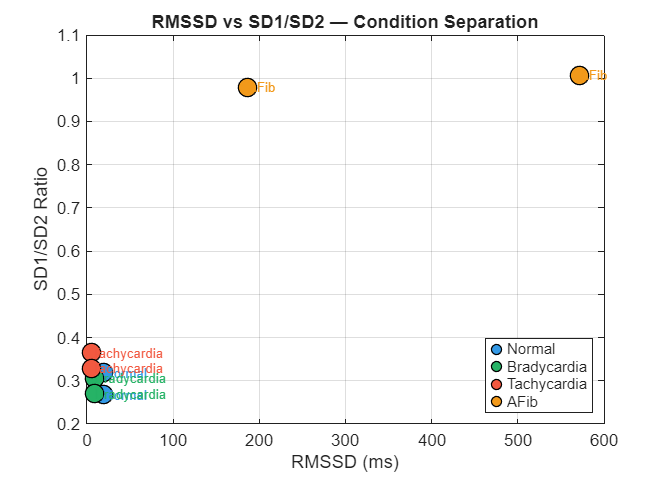


% -- 5e: RMSSD vs SD_ratio scatter --
figure('Name','RMSSD vs SD_ratio','NumberTitle','off','Position',[200 150 700 500]);
hold on; lgd2 = {};
for c = 1:n_cond
    rx = []; ry = [];
    for d = 1:2
        if ~isempty(cond_feats{c,d})
            rx(end+1) = cond_feats{c,d}.RMSSD;   %#ok
            ry(end+1) = cond_feats{c,d}.SD_ratio; %#ok
        end
    end
    scatter(rx,ry,120,colors{c},'filled','MarkerEdgeColor','k','LineWidth',0.8);
    text(rx+0.5,ry,conditions{c},'FontSize',8,'Color',colors{c});
    lgd2{end+1} = conditions{c}; %#ok
end
xlabel('RMSSD (ms)'); ylabel('SD1/SD2 Ratio');
title('RMSSD vs SD1/SD2 — Condition Separation');
legend(lgd2,'Location','best');
grid on; box on; hold off;


fprintf('\nDone. All sections complete.\n');


Done. All sections complete.
